# **ICESat-2 Elevation Differencing User Guide**

**For use with MATLAB and ICESat-2 level 3A ATL06 and ATL08 data products.**

Colten M. Elkin, 2021

For questions please contact the author at coltenelkin@u.boisestate.edu or the author's advisor Dr. Ellyn Enderlin at ellynenderlin@boisestate.edu.

I'd like to thank Boise State undergraduate student Maddie Gendreau for her help in creating and testing this User Guide. 

## 1. Background and Motivation

    This user guide will walk you through the steps to calculating elevation differences between ICESat-2 and reference data sets. It may be worthwhile to skim my Master's Thesis (Assessment of ICESat-2 level 3A products for snow depth estimation in remote, mountainous watersheds; published 2021 through Boise State University's digital commons) before using this guide. By the end of this live script, you'll be able to download ICESat-2 data, read it into matlab, save the variables that you need in the regions that you're interested in, and compare elevation residuals (differences) between ICESat-2 data points and reference data. With the data, you'll also be able to generate output figures directly in Matlab that compare elevation residuals to terrain parameters similar to figure 1.

**Important notes before you begin: **

- You'll need to have a registered earthexplorer account with the USGS. Have your email and password handy for the data download step.

- You'll need each of the following for this analysis: A shapefile of your region of interest; a digital elevation model (tif) or lidar data (las files) that will serve as reference elevations for your region of interest. 

- Each of the steps is accurate at the time that this guide was written (in Matlab_R2020b). I'm currently on a Mac desktop running OS Mojave version 10.14.6. I also use Google Chrome as my primary internet browser. All that said, there may be some minor changes due to updates in Matlab, Mac OS, and the online ICESat-2 data portal available through the NSIDC. It would be useful to have some general coding and data sourcing background before using this guide in case you need to troubleshoot errors caused by version differences. 

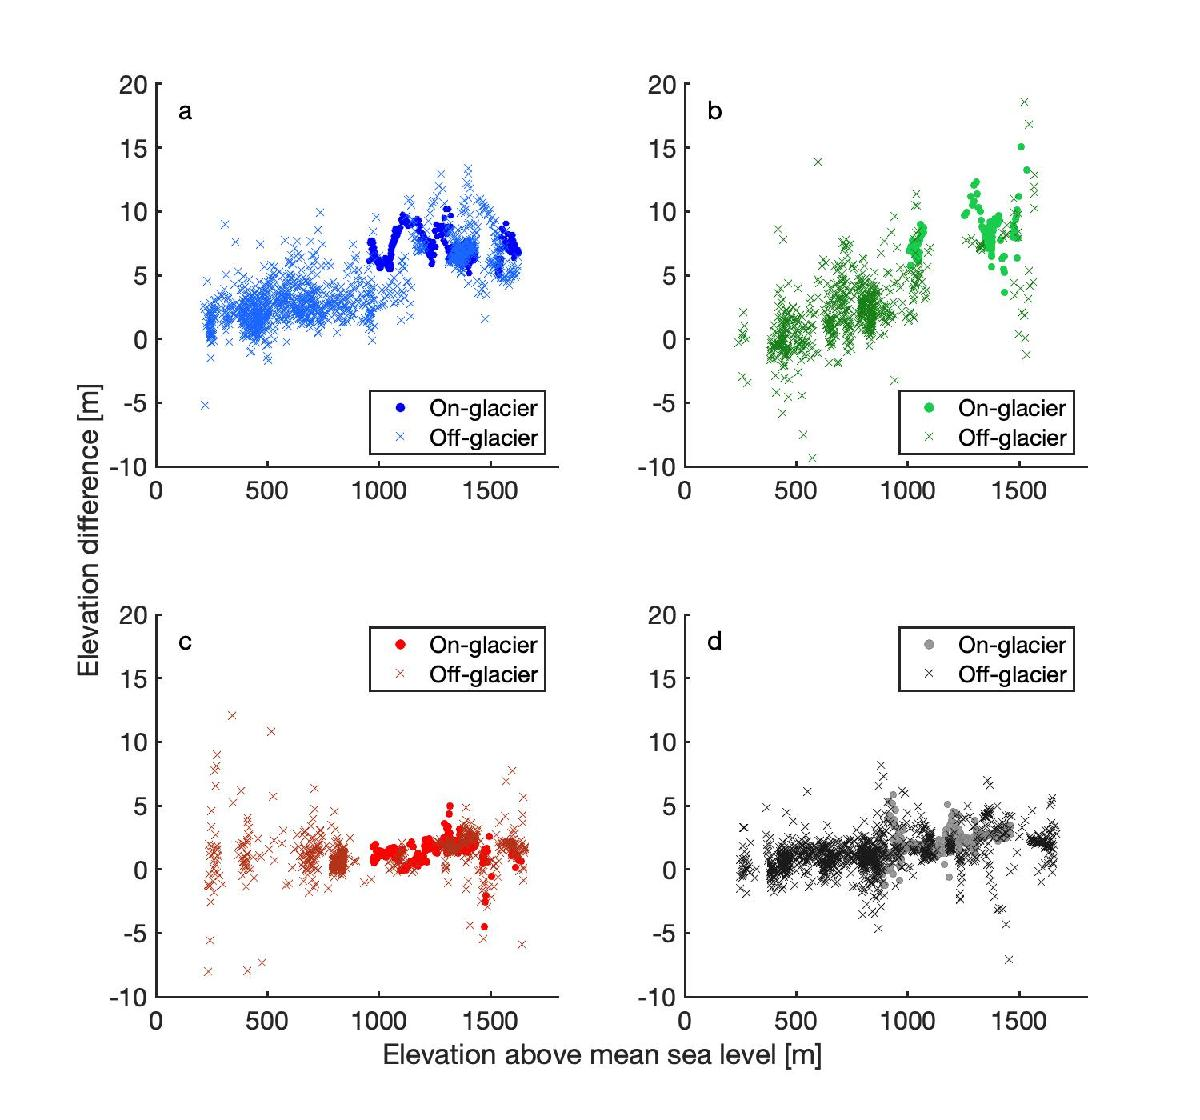

**Figure 1. An example of the type of figure that you'll be able to generate by the end of this user guide.**

## **2. Downloading ICESat-2 data**

- Access the ICESat-2 data portal through the National Snow and Ice Data Center (NSIDC). At the time of writing, that data portal is available here: https://nsidc.org/data/icesat-2 

- Click on the Level-3A tab on the left side of the browser. 

- Click on the data product that you're interested in (either ATL06 or ATL08). If your study site is on or near a glacier, you're better off with ATL06. If your site is not near a glacier, use ATL08. The differences between the data products are only mentioned when necessary in this user guide. For a more detailed description of either please see the aforementioned Thesis or the ATL06 and ATL08 technical documents.

- Zoom in to your area of interest and draw a bounding box or polygon around it. You can also narrow your search by date using the date filter tabs above the image of the Earth (figure 2). Note that you'll be clipping the ICESat-2 files down to your specific region of interest in Matlab, so you should just draw a rough box that completely includes your study area.

- Once you have your area of interest and your date range, click on the blue 'download script' button at the bottom of the page. You may be prompted that these types of downloads are potentially harmful (that's chrome's normal warning for downloading python scripts). Click 'keep' and it will begin a quick download. Keep this web page open through the next 2 steps.

- Click on the file that you've just downloaded. It should by a python script that opens in IDLE or text edit (or a similar software). You'll see in the top section that it has instructions for opening and running the script in your terminal. However, you may need to 'save as' this file so that the name matches exactly what you're going to call in your terminal (i.e. the command line calls nsidc-data-download.py, so you'll need to save the file as that name). 

- Open the terminal and run the program (in the mac terminal the line will be $ python nsidc-data-download.py). You'll be prompted to enter your earthexplorer account login information. Once you've entered your username and password, the files will download. 

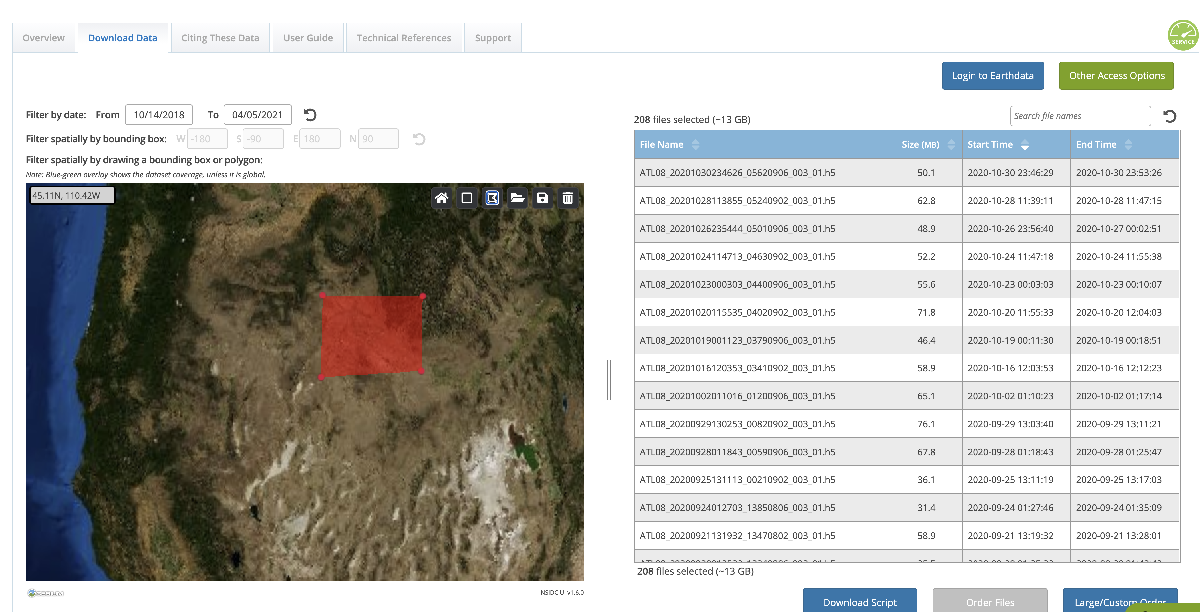

**Figure 2. **An example of the ATL08 data download page with my area of interest (the greater Treasure Valley area in Idaho) highlighted. You can filter by date or by bounding coordinates using the boxes above the satellite image of Earth. 

## 3. Saving the ICESat-2 Files to .csv format using Matlab

- Download the deg2utm function from Matlab's file exchange 

- Download and open the write_icesat2_csv.m function available with this user guide. Underneath the header comments there's an addpath() line. Add the path pointing to the deg2utm script that you downloaded and saved in step 1. This will allow the write_icesat2_csv funtion to call the deg2utm function as it runs.

- Open a live script that you'll use to fun the following functions:

- Run write_icesat2_csv. The function requires the input directory pointing to your .h5 files, an output directory (this doesn't have to be created yet -- the script will create the output directory if it doesn't exist), and a shapefile saved in a decimal-degree coordinate system. 

- Note that script will generate a bunch of orange errors when calling the geoidheight function. These errors are because our longitudes are in a [-180, 180] coordinate system. The geoidheight function can handle this and wraps them into a [0, 360] coordinate system. In short, the orange errors aren't an issue. 

## 4. Creating a tif from lidar files

    If you already have a DTM that is in UTM coordinates saved as a tif for your area of interest, skip this step and proceed to step 5. If you have a DTM but it's not in UTM coordinates, you'll need to reproject it into the UTM coordinates associated with your area of interest and save that as a tif. I find that's easiest to do in QGIS, a free mapping software. I'm sure it can also be done in Matlab.

- Download LASReadLastReturn.m, available with this user guide. LASReadLastReturn is modified from Alexander, 2020's LASRead.m which is available through Matlab's file exchange here (https://www.mathworks.com/matlabcentral/fileexchange/21434-lasread). The modified LASReadLastReturn used here looks only at ground return photons so it theoretically ignores canopy coverage. 

- Save the script to your working directory (or add it to your paths). 

- Work through the las2csv.mlx live script copied below. This takes quite a bit of time. The outputs will be txt files that include easting, northing, and elevation. 

- Work through the downsampling.mlx live script copied below. This also takes quite a bit of time. The final output will be a raster at your desired resolution.

    This section varies from each of the others in that it requires a live script instead of a function. I've copied the script that I used to create a DTM of the Reynolds Creek area in southwest Idaho. You'll need to adjust the paths in the user input section at the top of the script.

% the purpose of this kernel is to transform .las files to .csv
% files so that they can be used with my python code

% works with v1.1 LAS files; for v1.2 open LASRead.m and 
% look at the top comments section. There's a pretty simple
% change to make it compatible with v1.2

% created 12 July 2020 by C. Elkin (coltenelkin@u.boisestate.edu)

% Last modified 4 October 2020 
% Most Recent Change: use LASReadLastReturn.m (modified from
% LASRead.m to only report the last return (terrain elevation rather than
% canopy elevation). 

% utilizes LASReadLastReturn, which was built off of LASRead, cited here: 
% Cici Alexander (2020). LASRead (https://www.mathworks.com/matlabcentral/fileexchange/21434-lasread), MATLAB Central File Exchange. Retrieved July 13, 2020.


####     Modify these parameters to pull the .las files that you want. Open LASRead.m for more detail on inputs/outputs.

addpath('/Users/glaciologygroup/Desktop/elkin/ms_code/LASRead'); % add path to matlab function

% set the input folder containing the las files of interest
infolder = '/Users/glaciologygroup/Desktop/elkin/ms_code/reynolds_creek_lidar/ReynoldsCreek2007/LAS';

% set or create an output folder for the resulting .csv files
outfolder = '/Users/glaciologygroup/Desktop/elkin/ms_code/LASRead/RCfirstreturns';

    **You shouldn't have to modify anything here.**

% This is the looping action that should take in the .las files
% from the input folder, turn them into .csv files utilizing 
% LASReadLastReturn, and save them to the output folder

tic % time this sucker
converted_files = 0; % initialize a counter to report out at the end of the script

% check to make sure that the input folder exists
if ~exist(infolder, 'dir')
    disp('Sorry, there is no such input folder.')
    check = 0;
    
%  if it exists, does the input folder have at least one .las file?
else 
    listing = dir(infolder);
    
    counter = 0;
    targettype = '.las';
    for i = 1:length(listing)
        files = {listing.name};
        file = files{i};
        if length(file) > 4
            filetype = file(end-3:end);
            if isequal(filetype, targettype)
                counter = counter + 1;
            end
        end
    end
    if counter > 0
        % check whether the output folder exists, if not create it
        if ~exist(outfolder, 'dir')
            mkdir(outfolder);
        end
        check = 1;
    else
        disp('Sorry, there were no .las files in that input folder.')
        check = 0;
    end
end
   
% now we're at the meat of the matter. Before proceeding use 'check'
% value to be sure that the input folder is valid and that 
% there is at least one .las file
if check == 1 % if the directory has las files
    targettype = '.las'; % pull only las files
    for i = 1:length(listing) % loop through each file in the input directory
        files = {listing.name}; % pull each name
        file = files{i}; % grab the first file
        if length(file) > 4 % check and make sure the length of the name is greater than 4 (for string matching)
            filetype = file(end-3:end); % grab the file extension
            if isequal(filetype, targettype) % if the file extension is .las, enter these commands
                infilename = [infolder,'/',file]; 
                outfilename = [outfolder,'/',file(1:end-4),'.txt'];
                LASReadLastReturn(infilename, outfilename); % this is the actual las read step
                converted_files = converted_files + 1; % add one to the file counter
                if converted_files/5 == floor(converted_files/5) 
                    converted_files % report out every 5 converted files
                end
            end
        end
    end
end
    
toc
fprintf('The number of .las files converted to .txt files was %4.0f. \n', converted_files) % print out the total number of las files converted

####     Downsampling time. Modify these inputs to point towards your .txt files created in the code above. 

% clean downsampling live script. The goal is to read in csv files
% output by the las2csv.mlx live script, downsample those data, 
% and turn them into an elevation raster at [binsize]-meter resolution

% created 12 September 2020 by C. Elkin

% last modified 3 October 2020. Code seems to be at reasonable
% efficiency. Got estimated time for RC raster creation down from
% ~86 days to ~4 hours

% most recent change: lines at bottom before export that fill in vertical
% and horizontal NaN striping

% this is the user input section. 

% read in the desired folder with txt extensions. * is the wildcard operator
infolder = '/Users/glaciologygroup/Desktop/elkin/ms_code/LASRead/RCfirstreturns/BIN*.txt'; % path to files

% mac (/) or PC (\) directory divider
divider = '/'; % input which divider your OS uses to separate directories


% set bin size (in meters, integer >= 1). THIS IS YOUR RASTER RESOLUTION. 
binsize = 2; 

% path to a shapefile with the bounds of the watershed/region of interest (UTM Coordinates)
shapepath = '/Users/glaciologygroup/Desktop/elkin/ms_code/RC_shapefile/reynoldsck_utm.shp';

% desired ouput name for the final raster and csv products (same base name
% with different file extensions)
tiffname = 'RC_Downsampled_firstreturn.tif';
csvname = 'RC_downsampled_firstreturn.csv';

% the CRS EPSG Code for the projection of the output tiff. 
% 32611 is the code for UTM zone 11 N
crs_code = 32611;

**    Now we downsample. Again, you shouldn't have to modify this bit. **

% this subsection sets the files for the outermost loop
files = dir(infolder); % call all of the files in the input folder name
numfiles = length({files.name}); % get the number of files in the directory for looping
filenames = {files.name}; % create a cell array of just the file names
folder = {files.folder}; % create a cell array of just the path
folder = folder(1); % pull out the first path (each of the paths should be identical)
folder = folder{:}; % turn the cell variable into a character array

% this subsection sets up the initial grid for the watershed. It also sets
% up a NaNs array to store the eventual elevation values
shp = shaperead(shapepath); % read in the vectorized shapefile for the watershed
xlower = floor(nanmin(shp.BoundingBox(:, 1))); % get lower x value from the read shapefile
xupper = ceil(nanmax(shp.BoundingBox(:, 1))) + binsize; % get upper x value from the read shapefile
ylower = floor(nanmin(shp.BoundingBox(:, 2))); % get lower y value from the read shapefile
yupper = ceil(nanmax(shp.BoundingBox(:, 2))) + binsize; % get upper y value from the read shapefile

xbins = xlower:binsize:xupper; % set x bins for the watershed
ybins = ylower:binsize:yupper; % set y bins for the watershed

elevation_raster = nan([length(xbins), length(ybins)]); % set the elevation array

% this subsection is the looping section that reads in the files, averages
% the elevation values that fall within a given grid cell, and repeats for
% each grid cell. 

tic % time the loop

for a = 1:numfiles
    filecall = filenames(a); % pull the a-th filename
    filecall = filecall{:} % turn the cell variable into a character array
    infile = [folder, divider, filecall]; % create the character array pointing the loop to which file to load
    
    elevationdata = readtable(infile); % read in the data
    elevations = table2array(elevationdata); % turn the table data to array data
    
    minx_in_file = nanmin(elevations(:,1)); % find the smallest x value in the currently open bin
    maxx_in_file = nanmax(elevations(:,1)); % find the largest x value in the currently open bin
    x_start_and_stop = find(xbins>=minx_in_file & xbins<ceil(maxx_in_file)); % find bins that have data for this file
    
    test_count_z = 0; % count the number of elevations that get stored
    
    for i = 1:(length(x_start_and_stop)-1)
        
        elevations = elevationdata; % we only want to load the file in once, and this keeps us from doing
        % it over and over again a bit further down
        
        elevations = table2array(elevations); % make the data an array instead of a table
        Ix = find(elevations(:,1)>=xbins(x_start_and_stop(i)) & elevations(:,1)<xbins(x_start_and_stop(i+1))); % find the x data inside the bin
        
        miny_in_file = nanmin(elevations(:,2));
        maxy_in_file = nanmax(elevations(:,2));
        y_start_and_stop = find(ybins>=miny_in_file & ybins<ceil(maxy_in_file));
        
        elevationsx = elevations(Ix,:); % subset to just the x indices of interest
        
        for j = 1:(length(y_start_and_stop)-1)
            elevations = elevationsx; % reset the elevations array to the x indices of interest
            Iy = find(elevations(:,2)>=ybins(y_start_and_stop(j)) & elevations(:,2)<ybins(y_start_and_stop(j+1))); % of the remaining values in
            % 'elevations', find the y indices falling within the y bin
            
            elevations = elevations(Iy, :); % save only those data in the y bounds
            
            zreport = nanmean(elevations(:,3)); % average and save the remaining elevation values
            
            if ~isnan(zreport) % only report if the zreport value is NOT a NaN
                test_count_z = test_count_z+1;
                if isnan(elevation_raster(x_start_and_stop(i),y_start_and_stop(j))) % only report if the elevation_raster value IS a NaN
                    elevation_raster(x_start_and_stop(i),y_start_and_stop(j)) = zreport; % report the elevation into the raster
                end
            end
        end
    end
    % print the number of elevations recorded in boxes
    fprintf("For file %3.0f the z count value was %3.0f.\n \n", a, test_count_z)
    
    % save to be safe every 50 iterations through the loop
    if a/50 == floor(a/50)
        writematrix(elevation_raster, 'RC_downsampled.csv'); % save the elevations as a csv every 50 files
        fprintf(' \n The matrix has been saved as a csv file. \n')
    end
end
% rotate the matrix 90 degrees. Somewhere in my loop I have my Xs and Ys
% confused and I don't want to try and figure out how to switch the
% scanning
true_elevations = rot90(elevation_raster);

% fill in the gaps in the matrix (interpolate in case of stripes of no data/NaN values in final raster
[numrow, numcol] = size(true_elevations); % get number of rows and columns
for indrow = 2:(numrow-1)
    for indcol = 2:(numcol-1)
        if isnan(true_elevations(indrow, indcol)) % loop through and replace horizontal nan bars with average from cell above and below
            true_elevations(indrow, indcol) = ((true_elevations(indrow-1, indcol) + true_elevations(indrow+1, indcol))/2);
        end
        if isnan(true_elevations(indrow, indcol)) % now replace vertical nan bars with average from cell left and cell right
            true_elevations(indrow, indcol) = ((true_elevations(indrow, indcol-1) + true_elevations(indrow, indcol+1))/2);
        end
    end
end

% at the end of the loop save the elevation matrix as a csv file
writematrix(true_elevations, csvname);

toc % report the total elapsed time




% export the matrix as a geotiff
R = maprefcells(); % create a map cells reference object
R.XWorldLimits = [xlower xupper]; % modify R to suit our needs using known vars
R.YWorldLimits = [ylower yupper];
R.RasterSize = size(true_elevations);
R.ColumnsStartFrom = 'north';

geotiffwrite(tiffname,true_elevations,R,"CoordRefSysCode",crs_code)



## 5. Coregistering ICESat-2

    This step makes use of Matlab's fminsearch function. If you're unfamiliar with fminsearch, feel free to look up the documentation online. Essentially, fminsearch takes a function with at least one output (dependent) parameter and tries to minimize it by adjusting at least one input (independent) parameter. You should note that fminsearch requires an initial guess; with some functions there are multiple minima (think of a sine wave) and fminsearch only finds a local minimum near the initial guess, not necessarily the global minimum. 

- Open a new live script (.mlx) file or continue using the one you used in step 3. 

- Load in your DTM (saved as a tif) and the map reference object associated with it. The command will look something like *[myDTM, myRef] = geotiffread('myDTMfile.tif')*

- Create a variable that is a string pointing to one of the csv files created in section 3. The command will look like *myICESat2 = '/Users/icesat2/myfile_gt1r.csv'*

- Create a function handle of coregister_icesat2.m (available with this user guide) dependent on A. the command will look like *myFuncHandle = @(A)coregister_icesat2(myICESat2, myDTM, myRef, A)*

- The next step takes a considerable amount of time for each beam (an hour plus on my desktop -- it could vary significantly depending on your computer).

- Call fminsearch to minimize the output of coregister_icesat2. The output that you're minimizing is the root-mean-squared difference (RMSD) between the ICESat-2 elevations and the reference DTM elevations. Fminsearch is minimizing that value by adjusting horizontal offsets A(1), or offet in meters in the easting direction, and A(2), or offset in meters in the northing direction. Note that you'll have to give an initial A guess. DO NOT USE [0, 0]. There is a local minimum about [0,0] that fminsearch will find. Instead, use an arbitrary non-zero guess on the order of +/- 10 meters in both the easting and northing directions (I've used [-10, 20] in the past -- feel free to use your own non-zero values). You're going to want to save both the value of the minimized RMSD and the best offest values Abest(1), Abest(2) (I'd actually argue that the offset values are much more important). 

-         For step 6, the command line will look like *[Abest, RMSDbest] = fminsearch(myFuncHandle, [-10, 20])*

- Save the output Abest values. These offsets correspond to the specific ATL08/06 file and beam that you used when creating the function handle. If you're running through multiple beams and files, you'll need to come up with a way to save which ATL08/06 file and beam corresponds to which Abest outputs. I used cell arrays to save all of that info, but you can also create a table (or even manually copy and paste the values into an excel spreadsheet) to keep track. The offsets (and which files they go with) are computational gold. Everything else is relatively cheap to compute, so you'll definitely want to save these in at least one place that isn't your matlab workspace. 

- Use the Abest values as the offset input in icesat2_residuals.m. The icesat2_residuals.m script will calculate the point-by-point differences for each icesat2 transect using the horizontal offsets computed using coregister_icesat2.m. You'll want to save these values as well, but because this step takes a bit less time than calculating the horizontal offsets the Abest values (and which transects they correspond to) are *the most important values from this section*. 

## 6. Calculating Terrain Parameters at ICESat-2 Points   

    This section assumes that you have tifs of terrain parameters associated with your DTM. Terrain parameters can be elevation (a traditional DTM), vegetation cover height, slope, aspect, etc. I generated each of these tifs of terrain parameters using QGIS (if you load in a DTM as a raster, you can compute slope or aspect or any of a number of other parameters using built-in raster functions). I'm sure there's also a way to generate these terrain tifs in Matlab.

- Create variables pointing to your terrain tif and its map reference object. The command will look like *[myTerrainTif, myRef] = geotiffread('myTerrainFile.tif') *

- Create a variable that is a string pointing to one of the csv files created in section 3. The command will look like *myICESat2 = '/Users/icesat2/myfile_gt1r.csv'*

- Load in the Abest offset from section 5 associated with the specific ICESat-2 file that you just read in. The command will look like *myAbest = [Abest_associatedWithThisFile(1), Abest_associatedWithThisFile(2)]*

- Call and run calc_icesat2_params.m. The command will look like *params = calc_icesat2_params(myICESat2, myTerrainTif, myRef, myAbest)*

-     Note that you can also save the range and the standard deviation of the parameters within the bounding box representing the ICESat-2 footprint. You do this by saving multiple outputs from the calc_icesat2_params.m script. The command will look like *[params, range, stdev] = calc_icesat2_params(myICESat2, myTerrainTif, myRef, myAbest)*

- Save the parameter vector in the csv file. You can do this by loading in your .csv file as a table, saving the parameter vector in the table, and then writing the table back to where it was saved. It will look like this:

% assuming that you successfully ran steps 1-4 in this section:
myCSVfile = readtable('/Users/me/icesat2/myCSVfile_gt1r.csv'); % read the table
mylength = length(myCSVfile.Northing); % get the length of the ICESat-2 transect
params(mylength) = nan; % add a value at the end of params that is not a number (nan). 
% you need to do this because the parameter calculation step only reports
% the parameters from the first to the last-minus-oneth value.The parameter
% vector length needs to match the table vector length exactly
myCSVfile.param1 = params; % create a parameter column in the table and save the parameter vector to the table
writetable('/Users/me/icesat2/myCSVfile_gt1r.csv'); % save the table with the new parameter in its initial location

        6. Repeat steps 1 - 5 for all of the parameters that you want to save. Note that if you want to save the DTM elevations you'll need to perform these steps and save the outputs as DTMelevations in the csv file. The csv file as it sits (so before you save any new parameters) has elevations from ICESat-2, refined elevations using the geoidheight function (zRefined), and the Geoid height differences (Geoid). I recommend performing this section to get DTMelevations, slope, aspect, and VegHeight (where it applies). 